% Query all input devices
info = audiodevinfo;

fprintf('\n--- Available Input Devices ---\n');


--- Available Input Devices ---


if isempty(info.input)
    disp('No input devices found.');
else
    Devices = {info.input.Name}';
    IDs = [info.input.ID]';
    T = table(IDs, Devices);
    disp(T);
end

    IDs                               Devices                           
    ___    _____________________________________________________________

     0     {'Primary Sound Capture Driver (Windows DirectSound)'       }
     1     {'Microphone (USBAudio1.0) (Windows DirectSound)'           }
     2     {'Microphone Array (Realtek(R) Audio) (Windows DirectSound)'}




% Specific check for your IDs (1, 2, 3, 4)
checkIDs = [1, 2];
for id = checkIDs
    try
        devName = audiodevinfo(1, id);
        fprintf('ID %d is valid: %s\n', id, devName);
    catch
        fprintf('ID %d is INVALID or not connected.\n', id);
    end
end

ID 1 is valid: Microphone (USBAudio1.0) (Windows DirectSound)
ID 2 is valid: Microphone Array (Realtek(R) Audio) (Windows DirectSound)




Fs = 48000;
nBits = 16;
nChannels = 1;
duration = 5; % seconds



% rec3 = audiorecorder(Fs, nBits, nChannels, 3);   % <-- Mic 3
% rec4 = audiorecorder(Fs, nBits, nChannels, 4);   % <-- Mic 4

disp("Start Recording")

Start Recording


rec1 = audiorecorder(Fs, nBits, nChannels, 1);
rec2 = audiorecorder(Fs, nBits, nChannels, 2);

% Start both recorders back-to-back (non-blocking)
record(rec2, duration);
record(rec1, duration);


% Wait for recording to finish
pause(duration + 0.5);

disp("End of recording.")

End of recording.



mic1 = getaudiodata(rec1);
mic2 = getaudiodata(rec2);
% mic3 = getaudiodata(rec3);   % <-- Mic 3
% mic4 = getaudiodata(rec4);   % <-- Mic 4

% Fs = 48000; 
% nBits = 16;
% nChannels = 1;
% mic1 = readmatrix('present1.csv');
% mic2 = readmatrix('present2.csv');
% mic1_f = bandpass(mic1, [200 600], Fs);
% mic2_f = bandpass(mic2, [200 600], Fs);
% figure;
% subplot(2,1,1); plot(mic2_f(32001:62000)); title('Mic 1 (Filtered)');
% xline(12169,"r--",LineWidth=2);
% subplot(2,1,2); plot(mic2_f(40001:70000)); title('Mic 2 (Filtered)');
% xline(4169,"r--",LineWidth=2);

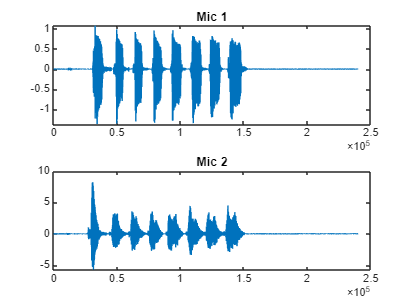


%% --- Plot raw signals ---
figure;
subplot(2,1,1); plot(mic1*10); title('Mic 1');
subplot(2,1,2); plot(mic2*10); title('Mic 2');

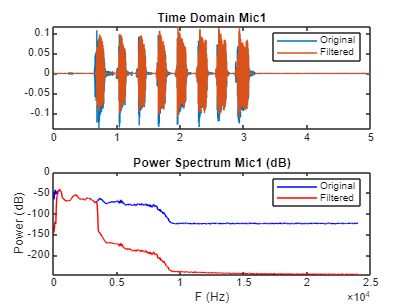

% subplot(4,1,3); plot(mic3*10); title('Mic 3');
% subplot(4,1,4); plot(mic4*10); title('Mic 4');

%% --- Trim to equal length ---
minLength = min([length(mic1), length(mic2)]);
mic1 = mic1(1:minLength);
mic2 = mic2(1:minLength);
% mic3 = mic3(1:minLength);
% mic4 = mic4(1:minLength);
t = (0:minLength-1) * (1/Fs);

%% --- Bandpass Filter ---
mic1_f = bandpass(mic1, [300 3400], Fs);
mic2_f = bandpass(mic2, [300 3400], Fs);
% mic3_f = bandpass(mic3, [200 600], Fs);   % <-- Mic 3
% mic4_f = bandpass(mic4, [200 600], Fs);   % <-- Mic 4

%% --- Plot filtered signals: Mic 1 & 2 ---
figure; subplot(2,1,1);
plot(t, mic1); hold on; plot(t, mic1_f);
title('Time Domain Mic1'); legend('Original','Filtered');
subplot(2,1,2);
[po1,fo1] = pspectrum(mic1, Fs);
[pf1,ff1] = pspectrum(mic1_f, Fs);
plot(fo1, 10*log10(po1), 'b'); hold on; plot(ff1, 10*log10(pf1), 'r');
title('Power Spectrum Mic1 (dB)'); xlabel('F (Hz)'); ylabel('Power (dB)'); legend('Original','Filtered');

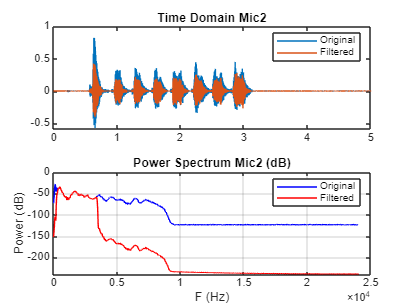


figure; subplot(2,1,1);
plot(t, mic2); hold on; plot(t, mic2_f);
title('Time Domain Mic2'); legend('Original','Filtered');
subplot(2,1,2);
[po2,fo2] = pspectrum(mic2, Fs);
[pf2,ff2] = pspectrum(mic2_f, Fs);
plot(fo2, 10*log10(po2), '-b'); hold on; plot(ff2, 10*log10(pf2), '-r');
title('Power Spectrum Mic2 (dB)'); xlabel('F (Hz)'); ylabel('Power (dB)'); legend('Original','Filtered');
grid on;

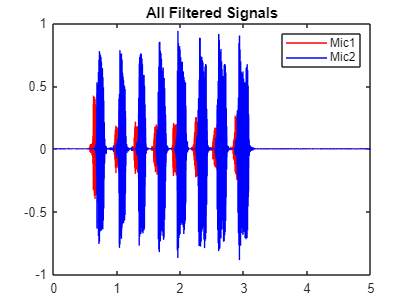


% %% --- Plot filtered signals: Mic 3 & 4 ---
% figure; subplot(2,1,1);
% plot(t, mic3); hold on; plot(t, mic3_f);
% title('Time Domain Mic3'); legend('Original','Filtered');
% subplot(2,1,2);
% [po3,fo3] = pspectrum(mic3, Fs);
% [pf3,ff3] = pspectrum(mic3_f, Fs);
% plot(fo3, 10*log10(po3), '-b'); hold on; plot(ff3, 10*log10(pf3), '-r');
% title('Power Spectrum Mic3 (dB)'); xlabel('F (Hz)'); ylabel('Power (dB)'); legend('Original','Filtered');
% grid on;
% 
% figure; subplot(2,1,1);
% plot(t, mic4); hold on; plot(t, mic4_f);
% title('Time Domain Mic4'); legend('Original','Filtered');
% subplot(2,1,2);
% [po4,fo4] = pspectrum(mic4, Fs);
% [pf4,ff4] = pspectrum(mic4_f, Fs);
% plot(fo4, 10*log10(po4), '-b'); hold on; plot(ff4, 10*log10(pf4), '-r');
% title('Power Spectrum Mic4 (dB)'); xlabel('F (Hz)'); ylabel('Power (dB)'); legend('Original','Filtered');
% grid on;

%% --- Overlay plots ---
figure;
plot(t, mic2_f, 'r'); hold on;
plot(t, mic1_f*8, 'b');
% plot(t, mic3_f, 'g');
% plot(t, mic4_f, 'm');
legend('Mic1','Mic2');
title('All Filtered Signals'); hold off;

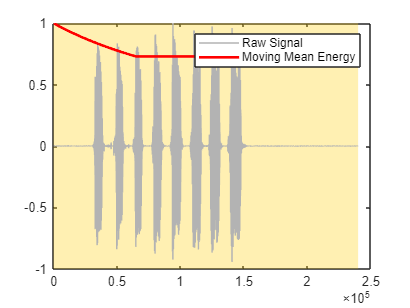

window = 350000;   % adjust based on Fs
% energy_amb = movmean(amb2_f.^2, window);

energy_mic = movmean(mic1_f.^2, window);
% Normalize the raw signal (absolute values) to a 0-1 scale
norm_mic = (mic1_f) / max((mic1_f));

% Normalize the energy to a 0-1 scale
threshold = mean(energy_mic) * 0.8;
active_idx = energy_mic > threshold;

norm_energy = energy_mic / max(energy_mic);
edges  = diff([0; active_idx; 0]);
starts = find(edges == 1);
ends   = find(edges == -1) - 1;
num_snaps = length(starts);
figure;
plot(norm_mic, 'Color', [0.7 0.7 0.7]); % Light gray for raw data
hold on;
plot(norm_energy, 'r', 'LineWidth', 2);  % Bold red for energy
for i = 1:num_snaps
    xregion(starts(i), ends(i), 'FaceColor', [1 0.8 0], 'FaceAlpha', 0.3);
end
legend('Raw Signal ', 'Moving Mean Energy');

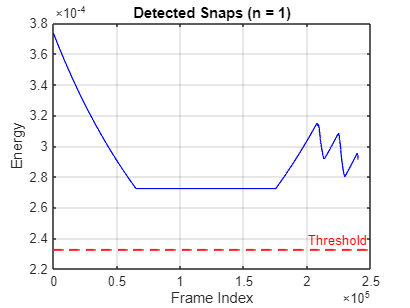


figure;
plot(energy_mic, 'b-', 'LineWidth', 1); hold on;
yline(threshold, 'r--', 'LineWidth', 1.5, 'Label', 'Threshold');
yline(threshold, 'r--', 'LineWidth', 1.2);

xlabel('Frame Index');
ylabel('Energy');
title(sprintf('Detected Snaps (n = %d)', num_snaps));
grid on;

Snap 1: Index 1 to 240000


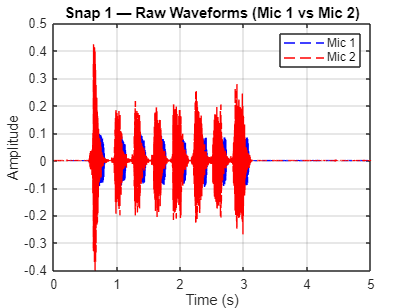

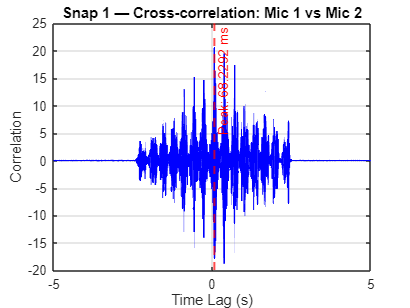

Delay Mic1-Mic2: 0.068229 s


Phi1: 0.00 deg



%% ── 3. Per-snap processing (Mic 1 & 2 Only) ────────────────────────────────
for i = 1:num_snaps
    s_idx = starts(i);
    e_idx = ends(i);
    fprintf('Snap %d: Index %d to %d\n', i, s_idx, e_idx);

    % Extract segments for Mic 1 and 2
    mic1_ac = mic1_f(s_idx:e_idx);
    mic2_ac = mic2_f(s_idx:e_idx);

    %% ── 3a. Raw waveforms ──────────────────────────────────────────────────
    t_snap = (0:length(mic1_ac)-1) / Fs;
    figure;
    plot(t_snap, mic1_ac, 'b--'); % Mic 1: Blue circles + dashed line
    hold on;
    plot(t_snap, mic2_ac, 'r--'); % Mic 2: Red circles + dashed line
    hold off;
    title(sprintf('Snap %d — Raw Waveforms (Mic 1 vs Mic 2)', i));
    xlabel('Time (s)'); ylabel('Amplitude'); 
    legend('Mic 1', 'Mic 2');
    grid on;

    %% ── 3b. Cross-correlation ──────────────────────────────────────────────
    [xc12, lags12] = xcorr(mic1_ac, mic2_ac);
    [~, idx12]     = max(abs(xc12));
    lag12          = lags12(idx12);
    delay12        = lag12 / Fs;

    figure;
    plot(lags12/Fs, xc12, 'b-', 'LineWidth', 1.2); hold on;
    xline(delay12, 'r--', 'LineWidth', 1.5, ...
          'Label', sprintf('Peak: %.4f ms', delay12*1e3));
    xlabel('Time Lag (s)');
    ylabel('Correlation');
    title(sprintf('Snap %d — Cross-correlation: Mic 1 vs Mic 2', i));
    grid on;

    %% ── 3c. Angle Estimation ───────────────────────────────────────────────
    c = 343;
    d = 0.3;
    val12 = (c * delay12) / d;
    phi1 = rad2deg(acos(max(-1, min(1, val12))));

    fprintf('Delay Mic1-Mic2: %.6f s\n', delay12);
    fprintf('Phi1: %.2f deg\n\n', phi1);
end

%% --- Constants & Calibration Indices ---
Fs          = 48000;
v_sound     = 343;
cal_end_idx = round(minLength * 2 / 10, 0);

% Calibration segments
m1_cal = mic1_f(1:cal_end_idx);
m2_cal = mic2_f(1:cal_end_idx);
% m3_cal = mic3_f(1:cal_end_idx);   % <-- Mic 3
% m4_cal = mic4_f(1:cal_end_idx);   % <-- Mic 4

% Measurement segments
m1_meas = mic1_f(cal_end_idx+1 : end);
m2_meas = mic2_f(cal_end_idx+1 : end);
% m3_meas = mic3_f(cal_end_idx+1 : end);   % <-- Mic 3
% m4_meas = mic4_f(cal_end_idx+1 : end);   % <-- Mic 4

%% --- TDOA: Pair 1-2 ---
mic_spacing_m    = 2;
max_delay_s      = mic_spacing_m / v_sound;
max_lag_samples  = round(max_delay_s * Fs);

[c_cal12, lags_cal12] = xcorr(m1_cal, m2_cal, 'normalized');
[~, idx_cal12]        = max(abs(c_cal12));
clag12                = lags_cal12(idx_cal12);

[xc12, lags12] = xcorr(mic1_f, mic2_f, 120, 'normalized');
[~, idx12]     = max(abs(xc12));
lag12_raw      = lags12(idx12);

lag12_corrected = lag12_raw;
delay12_s       = lag12_corrected / Fs;
distance12_m    = abs(delay12_s) * v_sound;

fprintf('\n--- Pair 1-2 ---\n');


--- Pair 1-2 ---


fprintf('Raw lag      : %d samples\n',   lag12_raw);

Raw lag      : 99 samples


fprintf('Calib offset : %d samples\n',   clag12);

Calib offset : 3451 samples


fprintf('Corrected lag: %d samples\n',   lag12_corrected);

Corrected lag: 99 samples


fprintf('TDOA delay   : %.6f s (%.4f ms)\n', delay12_s, delay12_s*1000);

TDOA delay   : 0.002063 s (2.0625 ms)


fprintf('Estimated distance offset: %.4f m\n', distance12_m);

Estimated distance offset: 0.7074 m



% %% --- TDOA: Pair 3-4 ---
% [c_cal34, lags_cal34] = xcorr(m3_cal, m4_cal, 'normalized');
% [~, idx_cal34]        = max(abs(c_cal34));
% clag34                = lags_cal34(idx_cal34);   % calibration offset for pair 3-4
% 
% [xc34, lags34] = xcorr(mic3_f, mic4_f, max_lag_samples, 'normalized');
% [~, idx34]     = max(abs(xc34));
% lag34_raw      = lags34(idx34);
% 
% lag34_corrected = lag34_raw;           % apply clag34 here if needed: lag34_raw - clag34
% delay34_s       = lag34_corrected / Fs;
% distance34_m    = abs(delay34_s) * v_sound;
% 
% fprintf('\n--- Pair 3-4 ---\n');
% fprintf('Raw lag      : %d samples\n',   lag34_raw);
% fprintf('Calib offset : %d samples\n',   clag34);
% fprintf('Corrected lag: %d samples\n',   lag34_corrected);
% fprintf('TDOA delay   : %.6f s (%.4f ms)\n', delay34_s, delay34_s*1000);
% fprintf('Estimated distance offset: %.4f m\n', distance34_m);

L = 1.6

L = 1.6000

theta12 = rad2deg(cos(delay12_s*343/L))

theta12 = 51.7859

% theta34 = rad2deg((delay34_s*343/L))

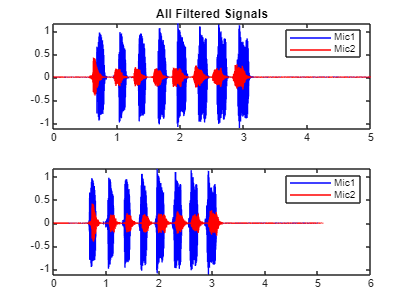

writematrix(mic1,"present1_bluetooth.csv")
writematrix(mic2,"present2_bluetooth.csv")